LAB TWO - PRELAB

%Matlab Synthesis of Chirps Signals
% 
% fsamp = 11025;
% dt = 1/fsamp;
% dur = 1.8;
% tt = 0 : dt : dur;
% psi = 2*pi*(100 + 200*tt + 500*tt.*tt);
% xx = real(7.7*exp(1j*psi));
% soundsc(xx, fsamp);

%3.2. Functfunction [xx,tt] = mychirp(f1,f2,dur,fsamp)
%{ 
MYCHIRP generate a linear-FM chirp signal

usage: xx = mychirp(f1,f2,dur,fsamp)
f1 = starting frequency
f2 = ending frequency
dur = total time duration
fsamp = sampling frquency (OPTIONAL: default is 11025)

xx = (vector of) sampls of the chirp signal
tt = vector of time instants for t=0 to t=dur
%}
% if(nargin<4), fsamp = 11025; end
% 
% tt = 0:1/fsamp:dur;
% xx = real(exp(1i*2*pi*(f1*tt+f2*tt.*tt)));
% soundsc(xx,fsamp);
% subplot(2,1,1)
% plot(tt,xx)
% subplot(2,1,2)
% specgram(xx,2048,fsamp); colormap;ion for a chirp


Advanced Topics: Spectogram

%Using specgram
% fs=8000; 
% xx = cos(3000*pi*(0:1/fs:0.5)); 
% specgram(xx,1024,fs); 
% colorbar


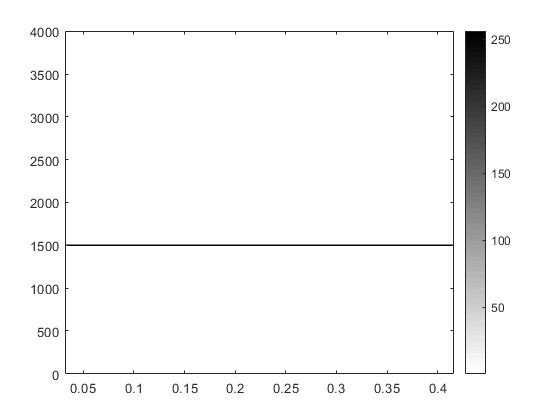

%Using plotspec
fs=8000; 
xx = cos(3000*pi*(0:1/fs:0.5)); 
plotspec(xx,fs,1024); 
colorbar

function [xx, tt] = beat(A, B, fc, delf, fsamp, dur)
%BEAT compute samples of the sum of two cosine waves
% usage:
% [xx, tt] = beat(A, B, fc, delf, fsamp, dur)
%%
%A = amplitude of lower frequency cosine
% B = amplitude of higher frequency cosine
% fc = center frequency
% delf = frequency difference
% fsamp = sampling rate
% dur = total time duration in seconds
% xx = output vector of samples
%--Second Output:
% tt = time vector corresponding to xx